# a

syms h(t)
Dh = diff(h);
ode = diff(h,t,2) + 6*diff(h,t) + 25*h == 0;
conds = [Dh(0)==-0.05 h(0)==0.15];
hSol(t) = dsolve(ode,conds);
hSol=simplify(hSol)

$$hSol(t) = \frac{{\mathrm{e}}^{-3\,t}\,\left(3\,\cos\left(4\,t\right)+2\,\sin\left(4\,t\right)\right)}{20}$$

# b

t=0:0.1:3

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000


hVector = eval(vectorize(hSol))

hVector =     0.1500    0.1312    0.0967    0.0600    0.0288    0.0064   -0.0071   -0.0132   -0.0141   -0.0120   -0.0086   -0.0052   -0.0024   -0.0004    0.0008    0.0013    0.0013    0.0011    0.0008    0.0004    0.0002    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000    0.0000    0.0000


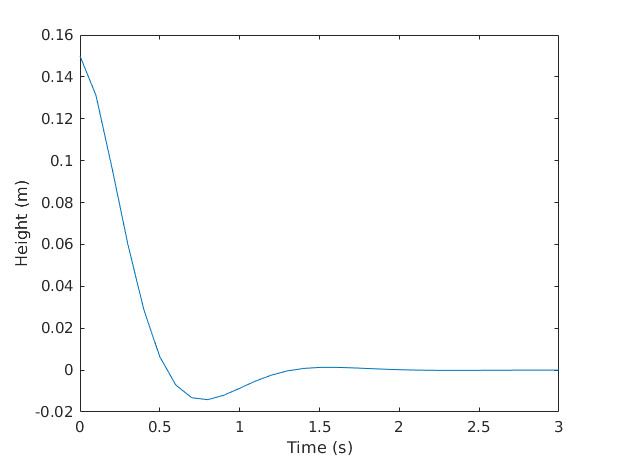

plot(t, hVector)
xlabel('Time (s)'); ylabel('Height (m)')
print('eps/topic6_b.eps','-depsc')

# c

syms h(t) w
Dh = diff(h);
ode = diff(h,t,2) + 6*diff(h,t) + 25*h == 2.5*exp(i*w*t);
conds = [Dh(0)==-0.05 h(0)==0.15];
General=simplify(dsolve(ode))

$$General = \begin{array}{l} C_{1}\,\cos\left(4\,t\right)\,{\mathrm{e}}^{-3\,t}-C_{2}\,\sin\left(4\,t\right)\,{\mathrm{e}}^{-3\,t}+\frac{5\,{\cos\left(4\,t\right)}^{2}\,{\mathrm{e}}^{t\,w\,\mathrm{i}}}{\sigma_{1}}+\frac{5\,{\sin\left(4\,t\right)}^{2}\,{\mathrm{e}}^{t\,w\,\mathrm{i}}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=2\,\left(-w^{2}+6\,w\,\mathrm{i}+25\right) \end{array}$$

Particular=simplify(dsolve(ode,conds))

$$Particular = \frac{{\mathrm{e}}^{-3\,t}\,\left(50\,\cos\left(4\,t\right)+25\,\sin\left(4\,t\right)+100\,{\mathrm{e}}^{t\,\left(3+w\,\mathrm{i}\right)}-6\,w^{2}\,\cos\left(4\,t\right)-4\,w^{2}\,\sin\left(4\,t\right)+36\,w\,\cos\left(4\,t\right)\,\mathrm{i}-w\,\sin\left(4\,t\right)\,\mathrm{i}\right)}{40\,\left(-w^{2}+6\,w\,\mathrm{i}+25\right)}$$

%% (ii)
w=[0:1:100]'; t=0:0.1:2

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


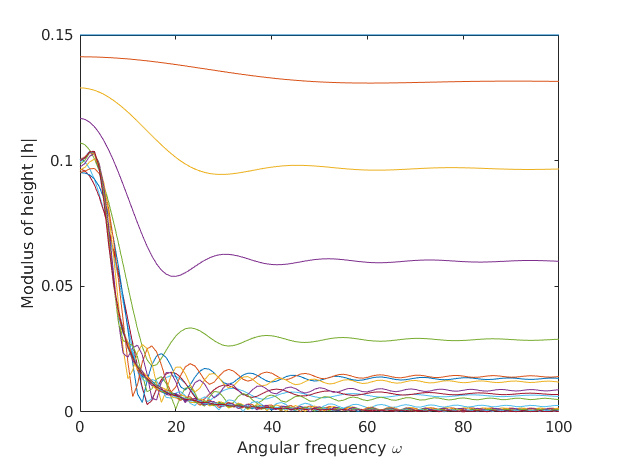

plot(w, abs(eval(vectorize(Particular))));
xlabel('Angular frequency \omega'), ylabel('Modulus of height |h|')
print('eps/topic6_c.eps','-depsc')